clc
clear all
close all

## **Reading DataFile: Omitting all rows with any text**

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [18, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Times", "Positionzmm", "Fzgf"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
RH0 = readtable("C:\Users\kondiboyina.v\Documents\Vineel\Nano-Indentation Results\Axolotl15cm\Uninjured\008R\008R_MC0.txt", opts);
savefile= 4; %Codenumber for saving file
part= 'HC'; %Codename for saving file

## Clear temporary variables

clear opts
A = table2array(RH0);
S=size(RH0); %Estimatesizeofarray


## **Parsing Sequence Files: Using t=0 as begining of new cycle**

t=0;j=1;x=1;y=1; % Initiating looping variables. i,j control rows and columns in T. x,y control M.
for i=2:1:S(1,1)
    if A(i,1)==0
       % t=max(M(:,y)); %Need to offset time after the first loop
         y=y+3;x=1;  %Increment and reset M loop   
    end
      for (j=1:3)  %looping through columns for each row in T
         M(x,y)=A(i,j);  %Saving data to a new matrix
         y=y+1; % looping through columns for each row in M   
    end
    x=x+1;
    y=y-3; %Resetting y so that we can loop through next row
end


%k is the number of columns in M
S=size(M);
k=S(1,2)-2;

## **Filter Non-sense/Blank Values**

for y=1:3:k
    for i=1:S(1,1)
        if M(i,y)==0 && M(i,y+1)==0 && M(i,y+2)==0
            M(i,y)=nan;
            M(i,y+1)=nan;
            M(i,y+2)=nan;
        end
    end
end

## **Adjust Time to Ensure All Cycles are Continuous**

for y=1:3:k-3
    t=max(M(:,y));
    M(:,y+3)=M(:,y+3)+t;
end

## **Seperate Different Sequences**

MovAbs= M(:,1:3);
ZeroLoad=M(:,4:6);
Contact=M(:,7:9);
Hold= M(:,10:12);
Unload=M(:,13:15);

## **Filtering Data to Reduce Noise**

HoldMovMean= movmean(Hold(:,3),10);
ContactMovMean= movmean(Contact(:,3),10);  %Used as filtered data. Data to be reported.
ContactMovMean2= movmean(Contact(:,3),20); %ContactMovMean2 is used to find contact point
%Adjust movmean2 window to find the right contact point.
UnloadMovMean= movmean(Unload(:,3),10);  %Used as filtered data. Data to be reported.

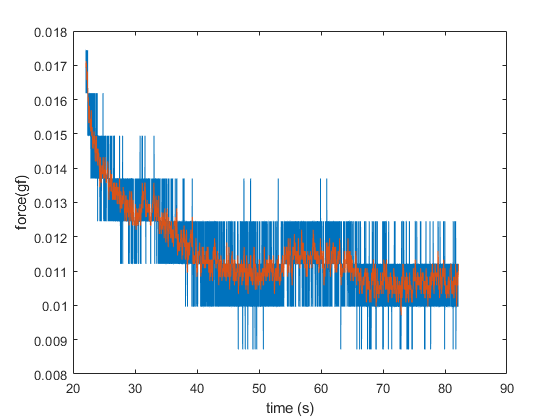

%Plot hold data
plot(Hold(:,1),Hold(:,3))
hold on
plot(Hold(:,1),HoldMovMean);
hold off
xlabel('time (s)')
ylabel('force(gf)')

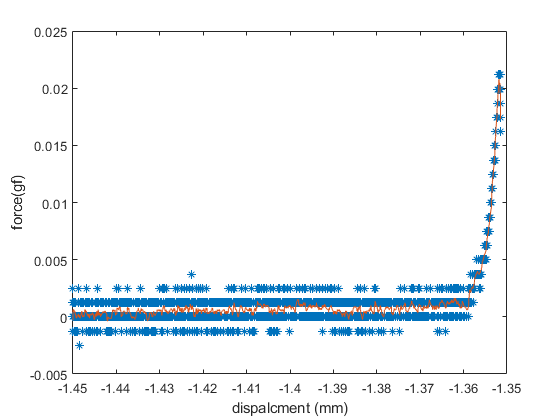

%Plot Contact data: raw and filtered. 
figure
plot(Contact(:,2),Contact(:,3),'*')
hold on
plot(Contact(:,2),ContactMovMean)
xlabel('dispalcment (mm)')
ylabel('force(gf)')

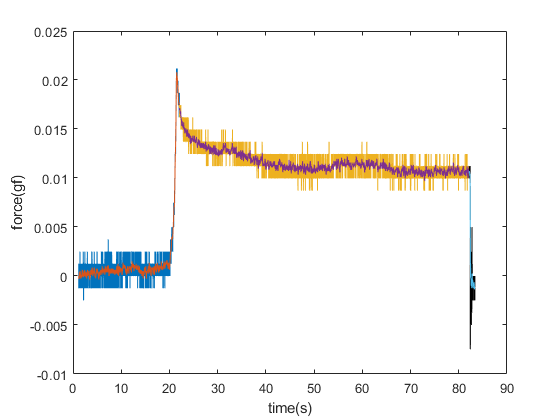

%Plot all data together
figure
plot(Contact(:,1),Contact(:,3))
hold on
plot(Contact(:,1),ContactMovMean)
hold on
plot(Hold(:,1),Hold(:,3))
hold on
plot(Hold(:,1),HoldMovMean);
hold on
plot(Unload(:,1),Unload(:,3),'k');
hold on
plot(Unload(:,1),UnloadMovMean);
hold off
xlabel('time(s)')
ylabel('force(gf)')

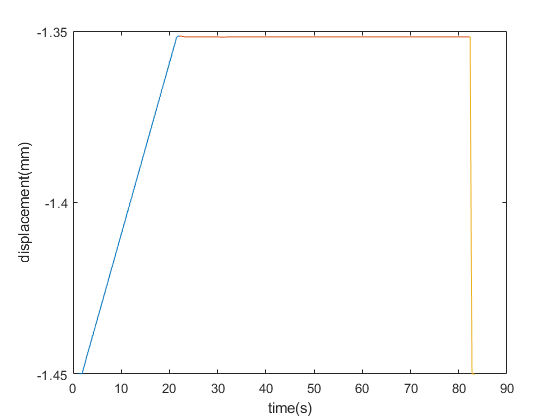


figure
plot(Contact(:,1),Contact(:,2))
hold on
plot(Hold(:,1),Hold(:,2))
hold on
plot(Unload(:,1),Unload(:,2))
hold off
xlabel('time(s)')
ylabel('displacement(mm)')

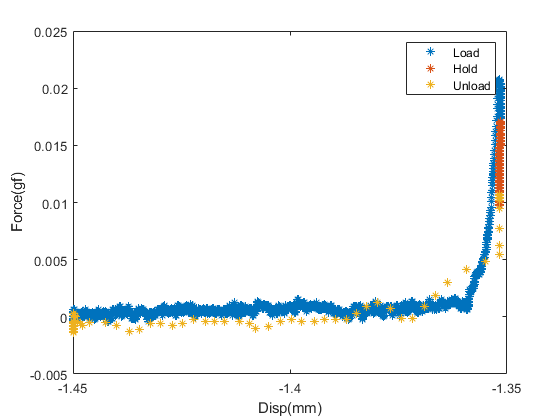


figure
plot(Contact(:,2),ContactMovMean(:,1),'*')
hold on
plot(Hold(:,2),HoldMovMean(:,1),'*')
hold on
plot(Unload(:,2),UnloadMovMean(:,1),'*')
hold off
xlabel('Disp(mm)')
ylabel('Force(gf)')
legend('Load','Hold', 'Unload')

%Saving Averaged Data to new table
SmoothContact= [Contact(:,1) Contact(:,2) ContactMovMean];
SmoothHold= [Hold(:,1) Hold(:,2) HoldMovMean];
T=table([Contact;Hold], [SmoothContact; SmoothHold]);


## **Estimate Peak Force**

[peakF,n]=max(Contact(:,3));
maxn=n;
slopemax= (ContactMovMean2(n,1)-ContactMovMean2(n-1,1))/(Contact(n,1)-Contact(n-1,1));

## **Estimate Contact Point: Change in Slope**

for i=n-10:-1:10
    slope= (ContactMovMean2(i,1)-ContactMovMean2(i-5,1))/(Contact(i,1)-Contact(i-5,1));
    if slope<10^-15*slopemax
        minn=i;
        break
    else
        minn=i+1000;
    end
end

## **Plot Max and Min Points on Filtered Data: Check for accuracy**

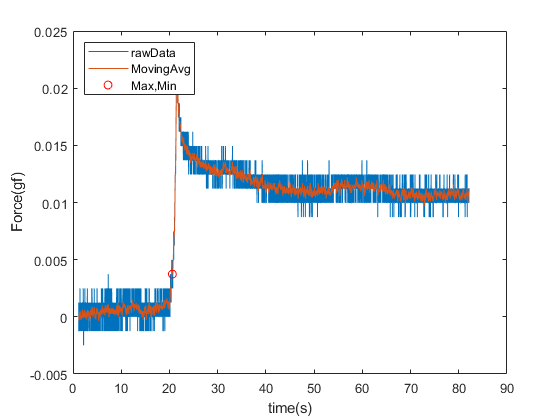

figure
plot(T.Var1(:,1),T.Var1(:,3))
hold on
plot(T.Var2(:,1),T.Var2(:,3))
hold on
a=Contact(minn,1);
b=Contact(minn,3);
c=Contact(maxn,1);
d=Contact(maxn,3);
plot(a,b,'o','color','r')
hold on
plot(c,d,'o','color','r')
xlabel('time(s)')
ylabel('Force(gf)')
legend('rawData','MovingAvg','Max,Min','Location','northwest')

## **Data plot: This is what is saved in text files**

x=1;
for i=minn:1:size(Contact,1)
    StressRelax(x,1) = Contact(i,1);
    StressRelax(x,2) = Contact(i,2);
    StressRelax(x,3) = ContactMovMean(i,1);
    x=x+1;
end
for i=1:1:size(Hold,1)
    StressRelax(x,1) = Hold(i,1);
    StressRelax(x,2) = Hold(i,2);
    StressRelax(x,3) = HoldMovMean(i,1);
    x=x+1;
end
StressRelax(:,1)= StressRelax(:,1)-StressRelax(1,1);
StressRelax(:,2)= StressRelax(:,2)-StressRelax(1,2);
StressRelax(:,3)= StressRelax(:,3)-StressRelax(1,3);

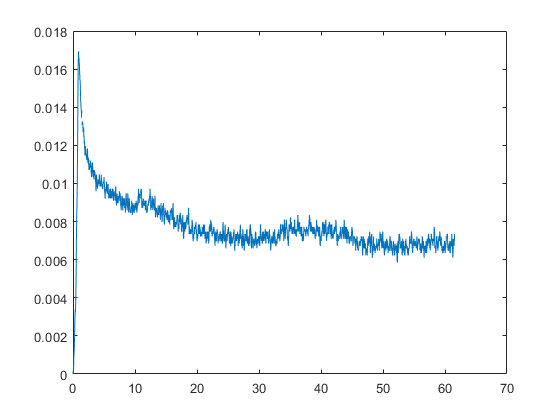

figure
plot(StressRelax(:,1),StressRelax(:,3))

## **Saving to Text File**

fileID = sprintf('%s_%d.txt',part,savefile); %The Filename is initiated at the very begining
dlmwrite(fileID, StressRelax, 'delimiter',' ');